# Aula 5 - Laboratório de Controle - 2023/1

## **Resposta no tempo de sistemas de segunda ordem: regime e transitório**

## Nome: (seu nome aqui)

**Ler o **[material complementar](https://drive.google.com/file/d/1AxaHz_A5kj2AXabVccIWH5S6HSxy87G_/view?usp=share_link)[ ](https://classroom.google.com/c/NTE0NDk4OTQ4Mjgw/m/NTMxODU3Mzg0MTUz/details)**antes de começar a atividade. **

I=3;
[g2, Km]=init5(I);
b0=g2.Numerator{1}(3);p0=g2.Denominator{1}(3);
datetime('now')

ans = datetime
   18-Apr-2023 21:38:31


## Atividade 1 - Aproximação por sistema de primeira ordem

Analise a resposta ao degrau unitário de $g_2(s)$, que deve ser aproximada por um sistema de ordem 1. Use a figura 4.2 de [Livro](https://drive.google.com/file/d/1HAAmjsTySWHZxOE4OeSGI52DN-7iAT_f/view?usp=share_link)  como referência.

g2

g2 =
 
        100
  ---------------
  s^2 + 12 s + 20
 
Continuous-time transfer function.



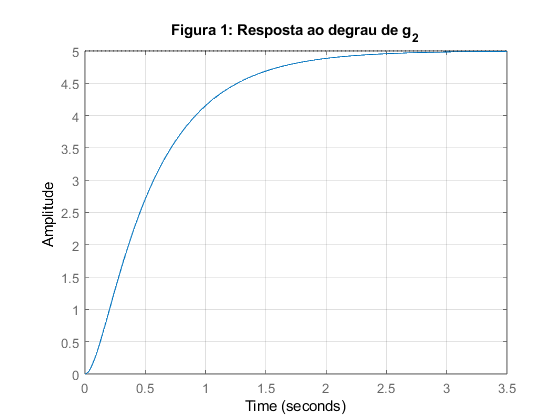

figure; 
step(g2);
grid minor;
title('Figura 1: Resposta ao degrau de g_2')

1.1 Obtenha a constante de tempo tau considerando a saída em 63% do valor de regime, e o ganho K, gerando a FT g1. Compare a aproximação de g2 por g1.

Resposta:

63.3*5/100 = 3.1650, do gráfico amplitude = 3.165 tau ~= 0.60 e K = 5

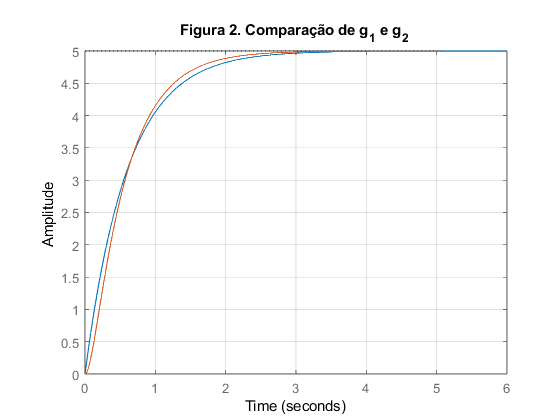

K=5; % Obter
tau=0.60; % Obter
figure;
g1=tf(K,[tau 1]);  % Substitua os valores de tau e K obtidos
step(g1,g2);grid minor; 
title('Figura 2. Comparação de g_1 e g_2');

1.2 Analise o lugar das raízes para g1 e para g2, verificando se o modelo g1 pode ser usado para prever o comportamento de g2 quando o ganho aumenta.

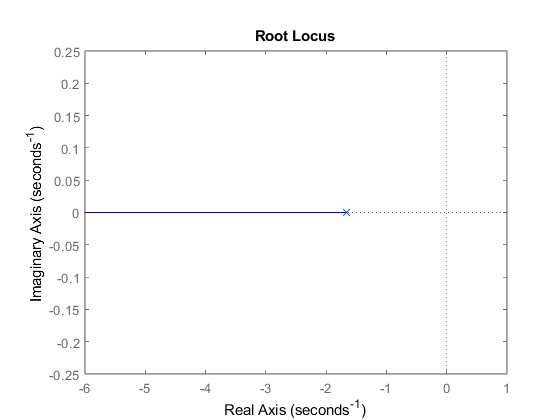

figure;
rlocus(g1);

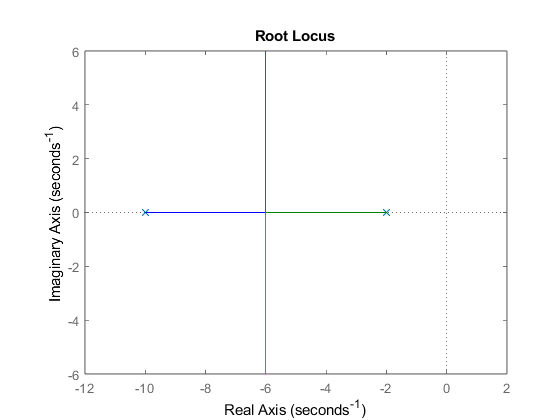

figure;
rlocus(g2);

Resposta:

Não, g1 não pode ser usado para prever o comportamento de g2, pois a direção que o polo caminha quando aumentamos o K  e seu destino final em $\;K\to \infty$ são totalmente diferentes.

## Atividade 2 - Análise do erro em regime

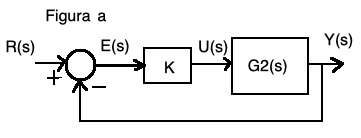

Abaixo são usados 20 valores de ganho $K$ para fechar a malha e calcular o [erro em regime. ](http://www.fem.unicamp.br/~em621/aulas/aula16/analiserro.pdf)$E(s)=\frac{R(s)}{1+KG_{2}(s)}$ para uma entrada degrau unitário $R(s)$, conforme a Figura a. 

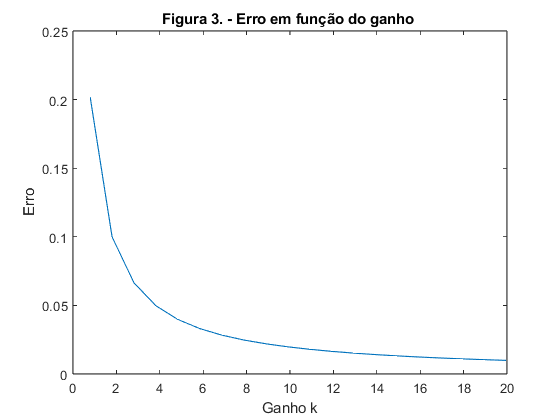

k=linspace(p0/(0.25*b0)-1/b0,p0/(0.01*b0)-1/b0,20);
for i=1:length(k)
    m=feedback(1,k(i)*g2);
    erro(i)=freqresp(m,0);% Teorema do valor final sobre E(s)
end
plot(k,erro);title('Figura 3. - Erro em função do ganho ');
xlabel('Ganho k');ylabel('Erro');

2.1 Qual o efeito do ganho no erro em regime? 

Quanto maior o ganho menor o erro em errige

2.2 Para que valores de ganho K o erro é menor que 5%? 

para K > 4 o erro em regime é menor que 5%

2.3 Qual o erro em regime para sistemas com tipo (ver [erro em regime ](http://www.fem.unicamp.br/~em621/aulas/aula16/analiserro.pdf)) igual ao de g2?

G2 é um sistema do tipo 0, logo o erro em regime será $\frac{1}{1+K}$

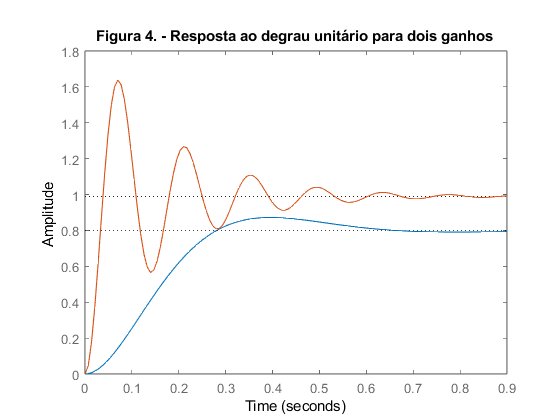

m1=feedback(k(1)*g2,1);
m2=feedback(k(end)*g2,1);
step(m1,m2);
title('Figura 4. - Resposta ao degrau unitário para dois ganhos');

2.4 Na figura 4 é mostrada a resposta ao degrau unitário para o menor e maior ganhos usados na figura 3. Compare o efeito do ganho K na resposta ao degrau unitário em regime e no período transitório, informando os ganhos usados  (obter da figura 3).

Resposta: O aumento do ganho contribui  para um tempo de subida menor, mas também influencia no tempo de estabelecimente e no sobressinal, com o maior ganho vemos que o sistema, apesar de rápido, oscila bastante e demora para estabilizar, já com o menor ganho o sistema é muito lento

## Atividade 3 - Análise da resposta transitória

A sobreelevação se relaciona com o amortecimento $\zeta$ pela equação $UP=100 e^-({\frac{\zeta \pi}{\sqrt{1-\zeta^2}}})$, com o efeito mostrado na figura abaixo.

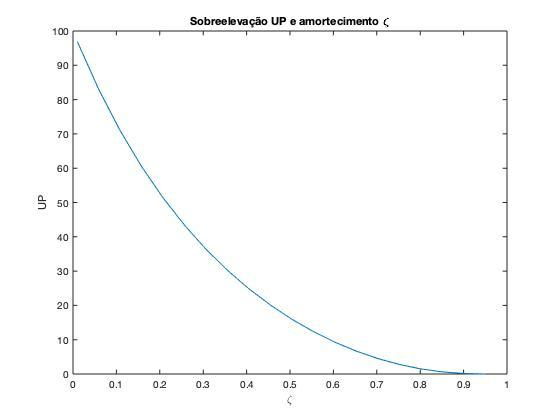

3.2 Use esta figura para obter aproximadamente os valores de $\zeta$para os quais se tem $UP\leq 5\%$.

Resposta:

Use os comandos abaixo para obter k1 de modo a ter $\zeta\geq0.7$ e k2 de modo a ter $\zeta\geq0.3$. 

K=linspace(0,Km,500);
rlocus(g2,K);grid;
k1=rlocfind(g2)
k2=rlocfind(g2)

Observe a sobreelevação e o tempo de estabelecimento obtidos com os ganhos k1 e k2.

m1=feedback(k1*g2,1);
m2=feedback(k2*g2,1);
figure;
step(m1,m2);
ss=sprintf('Figura 5. - Resposta ao degrau unitário para k1=%3.1f e k2=%3.1f',k1,k2);
title(ss);

3.3 Explique como usar o lugar das raízes para obter uma resposta que atenda aos requisitos de sobreelevação e tempo de estabelecimento, **e sugira uma especificação para este caso que atenda também um limite para o erro em regime.**

Resposta:

## Atividade 4: Parâmetros para especificar a resposta transitória

Nesta atividade são utilizados os valores de k1 e k2 da atividade anterior. 

Na figura abaixo é mostrada a resposta Y(s) ao degrau unitário R(s) bem como o erro E(s) e a integral absoluta do erro (IAE), calculada por $IAE=\int_{0}^{t}|e(t)|dt$. Observe que o IAE é integrado para cada instante de tempo t. O valor de IAE utilizado para comparações é aquele obtido na janela de tempo total. A patir de $t=0.6$ o erro fica nulo e o IAE torna-se constante, IAE=0.077.

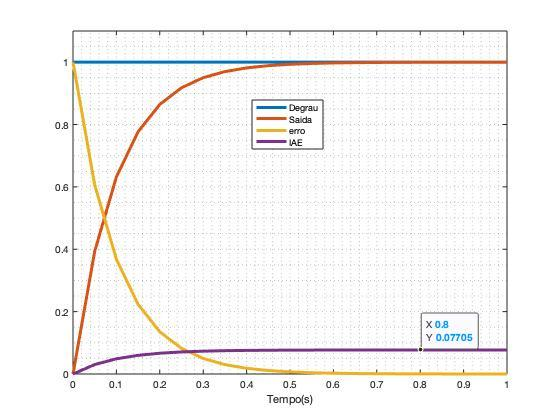

O script abaixo gera os parâmetros da resposta transitória, tempo de subida e de estabelecimento, sobreelevação, junto com o IAE em função do ganho, variando de k1 a k2 selecionados na atividade 3.

k=linspace(k1,k2,20); 
for i=1:20
    m=feedback(k(i)*g2,1);
    s=stepinfo(m);
    U(i,:)=[s.RiseTime s.SettlingTime s.Overshoot];
    if i==1 
        [y,t]=step(m);Tempo=max(t);
    else
        [y,t]=step(m,Tempo);
    end
    IAE(i)=trapz(t,abs(1-y));
end

subplot(4,1,1);bar(k,(U(:,1)));title('Figura 6. Tempo de subida (t_r) ');
subplot(4,1,2);bar(k,(U(:,2)));title('Tempo de estabelecimento (t_s)');
subplot(4,1,3);bar(k,(U(:,3)));title('Sobreelevação (UP)');
subplot(4,1,4);bar(k,(IAE));title('IAE');

4.1 Qual o efeito do ganho K no tempo de subida ($t_r$)? Qual o intervalo de variação de $t_r$?

Resposta:

4.2 Qual o efeito do ganho K na sobreelevação (UP)? Qual o intervalo de variação de UP?

Resposta:

4.3 Explique o comportamento do tempo de estabelecimento ($t_s$) quando o ganho K varia. Lembre-se que $t_s=\frac{4}{\zeta w_n}$ e observe o LR da atividade 3. 

Resposta:

Observe a figura 6 e a matriz abaixo, que mostra a correlação do IAE com $t_r$, $t_s$, UP (nesta ordem)

C=corr([IAE' U])

Observe também a figura 7 que usa os ganhos k(1), k(10), k(20) da figura 6 para ilustrar a relação do IAE com a qualidade da resposta transitória.  

m1=feedback(k(1)*g2,1);
m2=feedback(k(10)*g2,1);
m3=feedback(k(20)*g2,1);
figure;
step(m1,m2,m3);
ss=sprintf('Figura 7. - Resposta ao degrau unitário para k=%3.2f e k=%3.2f e k=%3.2f',k(1),k(10),k(20));
title(ss);
legend(num2str(k(1)),num2str(k(10)),num2str(k(20)))

4.4 Quem afeta mais o valor de IAE? UP, $t_r$ ou $t_s$? Justifique.

Resposta:

## **Importante: **

## **Ao final, dê o comando run, exporte como pdf e confira se todas as figuras foram geradas corretamente.**